# Solving the Timoshenko beam problem using sparse matrices and page-wise implementation

In this appendix it is demonstrated how to leverage [`sparse`](https://www.mathworks.com/help/matlab/ref/sparse.html)-matrices and [page-wise operations](https://blogs.mathworks.com/loren/2021/01/14/paged-matrix-functions/) in [MATLAB](https://www.mathworks.com/products/matlab.html)® to speed-up the computation, assembly and solution of the linear equation systems resulting from the discretization of the [Timoshenko beam](https://en.wikipedia.org/wiki/Timoshenko%E2%80%93Ehrenfest_beam_theory) *Boundary Value Problem* (BVP).

**Author: Andreas Apostolatos, PhD (aapostol@mathworks.com)**

**Date: 20.02.2023**

## Preamble

clc;
clear;
close all;

## **Problem parameters**

### Geometric parameters

Thickness [m]

propStr.t = 10^(-1);

Width [m]

propStr.b = .1;

Height [m]

propStr.A = propStr.b*propStr.t;

X-coordinate at the left end of the beam [m]

X0 = 0;

Y-coordinate at the right end of the beam [m]

XL = 4;

### Material paramerters

Distributed load along the beam's length [N/m^2]

propStr.qBar = -1e4*(propStr.t)^3;

Distributed moment along the beam's length [N/m]

propStr.mBar = 0;

Boundary force [N]

propStr.Q = 0;

Boundary moment [Nm]

propStr.M = 0;

Young's modulus [N/m^2]

propStr.E = 1e7;

Poisson ratio [dimensionless]

propStr.nu = 0.3;

Moment of inertia [m^4]

propStr.I = propStr.b*(propStr.t^3)/12;

Shear modulus (connected to epsilon_12 = E/(1+nu)) [N/m^2]

propStr.G = propStr.E/(2*(1 + propStr.nu));

Shear correction factor [dimensionless]

propStr.alpha = 5/6;

## Analytical solution

### Initialization of auxiliary variables

syms wEx(X) betaEx(X) QEx(X) Lsym qsym Gsym Acs alphaScf Aqsym Esym Isym

### Analytical solution with respect to the vertical deflection

wEx(X) = (qsym*Lsym*X-qsym*X^2/2)/Gsym/(Aqsym) - ...
    (-qsym*X^4/24+qsym*Lsym*X^3/6-qsym*Lsym^2*X^2/4)/Esym/Isym;

### Analytical solution with respect to the cross-sectional rotation

Get the analytical solution of the rotational field by leveraging the Partial Differential Equation (PDE) of the problem and the functions of the [Symbolic Math Toolbox](https://www.mathworks.com/products/symbolic.html)™ in [MATLAB](https://www.mathworks.com/products/matlab.html)®


$$\beta(X) = \int_{0}^L - \frac{1}{\alpha G A}\overline{Q} - \frac{\text{d}^2 w}{\text{d} x^2} \: \text{d}x \quad \quad (1)$$


betaEx(X) = int(-1/(propStr.alpha*propStr.G*propStr.A)*propStr.qBar - ...
    diff(diff(wEx, X), X));

### Evaluation of the expressions for the given geometric and material parameters

QEx(X) = alphaScf*Gsym*Acs*(diff(wEx(X), X, 1) + betaEx(X));

### Evaluation of the expressions for the given geometric and material parameters

wEx(X) = subs(wEx,{Lsym, qsym, Gsym, Esym, Isym, Aqsym}, ...
    {XL, propStr.qBar, propStr.G, propStr.E, propStr.b*(propStr.t^3)/12, ...
    propStr.alpha*propStr.b*propStr.t});
betaEx(X) = subs(betaEx,{Lsym, qsym, Gsym, Esym, Isym, Aqsym}, ...
    {XL, propStr.qBar, propStr.G, propStr.E, propStr.b*(propStr.t^3)/12, ...
    propStr.alpha*propStr.b*propStr.t});
QEx(X) = subs(QEx, {alphaScf, Gsym, Acs, Lsym, qsym, Gsym, Esym, Isym, Aqsym}, ...
    {propStr.alpha, propStr.G, propStr.A,XL, propStr.qBar, propStr.G, propStr.E, ...
    propStr.b*(propStr.t^3)/12, propStr.alpha*propStr.b*propStr.t});

## Verification of the the accuracy of the page-wise implementation

### Generation of an one-dimensional mesh using linear two-noded elements

#### Mesh generation

numElL1 = 7;
mshL1 = generateLinearMeshOnLine(X0, XL, numElL1);
numNodesL1 = numel(mshL1.nodes);

#### **Definition of the boundary conditions**

freeDOFsL1 = 1:2*numNodesL1;
numDOFsL1 = 2*numNodesL1;
homDOFsL1 = 1:2;
[~, idxL1] = ismember(homDOFsL1, freeDOFsL1);
freeDOFsL1(idxL1) = [];

#### Mesh plot

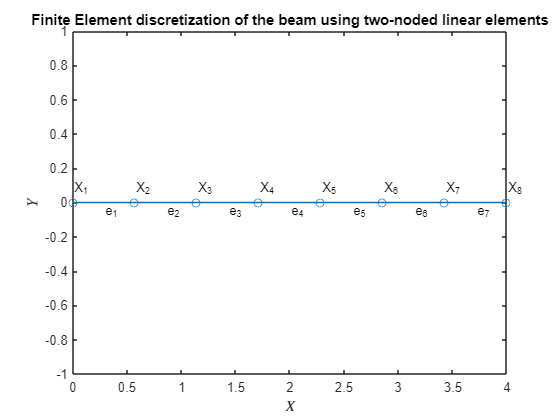

plotMesh1d(mshL1);
xlabel("$X$", Interpreter="latex")
ylabel("$Y$", Interpreter="latex")
title("Finite Element discretization of the beam using " + ...
    "two-noded linear elements")

### Generation of an one-dimensional mesh using quadratic three-noded elements

#### Mesh generation

mshL2 = generateQuadraticMeshOnLine(mshL1);
numNodesL2 = numel(mshL2.nodes);

#### **Define the boundary conditions of the problem for the mesh with the quadratic finite elements**

freeDOFsL2 = 1:2*numNodesL2;
numDOFsL2 = 2*numNodesL2;
homDOFsL2 = 1:2;
[~, idxL2] = ismember(homDOFsL2, freeDOFsL2);
freeDOFsL2(idxL2) = [];

#### Mesh plot

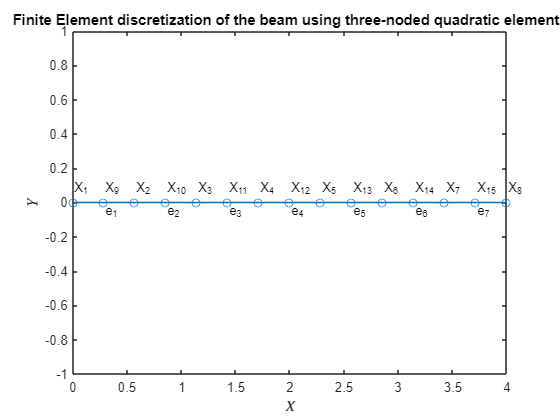

plotMesh1d(mshL2)
xlabel("$X$", Interpreter="latex")
ylabel("$Y$", Interpreter="latex")
title("Finite Element discretization of the beam using " + ...
    "three-noded quadratic elements")

### Computation of the master stiffness matrix and consistent nodal force vector with and without the page-wise implementation

#### Standard implementation for the one-dimenstional linear two-noded finite elements

computeStiffMatrixandForceVectorTB = ...
    @computeElementStiffMatrixandForceVectorTimoshenkoBeam;
computeBasisFunctionsAndDerivs = ...
    @computeLinearBasisFunctionsAndFirstDerivatives;
dummyInp = 'undefined';
[KL1, FL1] = computeMasterStiffMatrixandForceVectorTimoshenkoBeam ...
    (mshL1, computeStiffMatrixandForceVectorTB, computeBasisFunctionsAndDerivs, ...
    dummyInp, propStr);

#### Page-wise implementation using sparse matrices for the one-dimenstional linear two-noded finite elements

computeBasisFunctionsAndDerivs = @computeLinearBasisFunctionsAndFirstDerivatives;
computeStiffMatrixandForceVectorTB = 'undefined';
dummyInp = 'undefined';
[KPageWiseL1, FPageWiseL1] = ...
    computeMasterStiffMatrixandForceVectorTimoshenkoBeamPageWise ...
    (mshL1, computeStiffMatrixandForceVectorTB, computeBasisFunctionsAndDerivs, ...
    dummyInp, propStr);

#### Standard implementation for the one-dimenstional linear two-noded finite elements

computeStiffMatrixandForceVectorTB = ...
    @computeElementStiffMatrixandForceVectorTimoshenkoBeam;
computeBasisFunctionsAndDerivs = ...
    @computeQuadraticBasisFunctionsAndFirstDerivatives;
dummyInp = 'undefined';
[KL2, FL2] = computeMasterStiffMatrixandForceVectorTimoshenkoBeam ...
    (mshL2, computeStiffMatrixandForceVectorTB, computeBasisFunctionsAndDerivs, ...
    dummyInp, propStr);

#### Page-wise implementation using sparse matrices using sparse matrices for the one-dimenstional linear two-noded finite elements

computeBasisFunctionsAndDerivs = ...
    @computeQuadraticBasisFunctionsAndFirstDerivatives;
computeStiffMatrixandForceVectorTB = 'undefined';
dummyInp = 'undefined';
[KPageWiseL2, FPageWiseL2] = ...
    computeMasterStiffMatrixandForceVectorTimoshenkoBeamPageWise ...
    (mshL2, computeStiffMatrixandForceVectorTB, computeBasisFunctionsAndDerivs, ...
    dummyInp, propStr);

### Solution of the discrete linear equation system

#### Standard implementation for the one-dimenstional linear two-noded finite elements

uL1 = zeros(numDOFsL1, 1);
uL1(freeDOFsL1, 1) = KL1(freeDOFsL1, freeDOFsL1)\FL1(freeDOFsL1);

#### Page-wise implementation using sparse matrices for the one-dimenstional linear two-noded finite elements

uPageWiseL1 = zeros(numDOFsL1, 1);
uPageWiseL1(freeDOFsL1, 1) = ...
    KPageWiseL1(freeDOFsL1, freeDOFsL1)\FPageWiseL1(freeDOFsL1);

#### Standard implementation for the one-dimenstional quadratic three-noded finite elements

uL2 = zeros(numDOFsL2, 1);
uL2(freeDOFsL2, 1) = KL2(freeDOFsL2, freeDOFsL2)\FL2(freeDOFsL2);
[nodesL2, idx] = sort(mshL2.nodes);
wL2 = uL2(1:2:end, 1);
betaL2 = uL2(2:2:end, 1);

#### Page-wise implementation using sparse matrices for the one-dimenstional quadratic three-noded finite elements

uPageWiseL2 = zeros(numDOFsL2, 1);
uPageWiseL2(freeDOFsL2, 1) = ...
    KPageWiseL2(freeDOFsL2, freeDOFsL2)\FPageWiseL2(freeDOFsL2);
wPageWiseL2 = uPageWiseL2(1:2:end, 1);
betaPageWise_L2 = uPageWiseL2(2:2:end, 1);

### Postprocessing the discrete solutions

#### Visualization of the deformed configuration

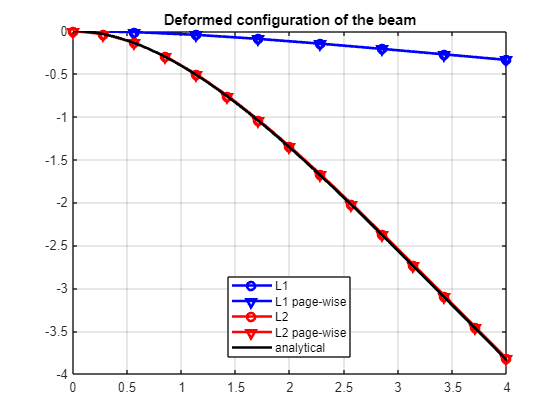

plot(mshL1.nodes, uL1(1:2:end, 1), '-bo', LineWidth=2)
hold on;
plot(mshL1.nodes, uPageWiseL1(1:2:end, 1), '-bv', LineWidth=2);
plot(nodesL2, wL2(idx), '-ro', LineWidth=2);
plot(nodesL2, wPageWiseL2(idx), '-rv', LineWidth=2);
fplot(wEx, [X0 XL], '-k', LineWidth=2);
hold off;
grid on;
legend("L1", "L1 page-wise", "L2", "L2 page-wise", "analytical", ...
    Location="best")
title("Deformed configuration of the beam")

#### Visualization of the cross-sectional rotation field

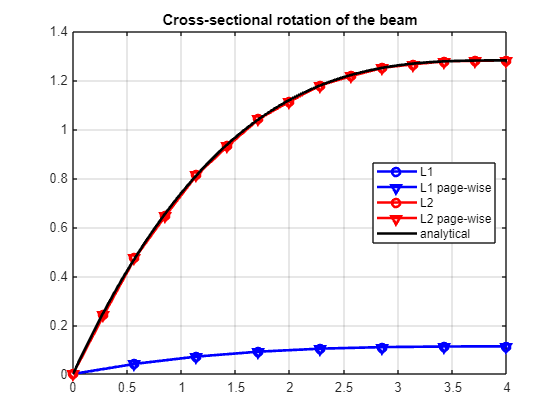

plot(mshL1.nodes, uL1(2:2:end, 1), '-bo', LineWidth=2)
hold on;
plot(mshL1.nodes, uPageWiseL1(2:2:end, 1), '-bv', LineWidth=2);
plot(nodesL2, betaL2(idx), '-ro', LineWidth=2);
plot(nodesL2, betaPageWise_L2(idx), '-rv', LineWidth=2);
fplot(betaEx, [X0 XL], '-k', LineWidth=2);
hold off;
grid on;
legend("L1", "L1 page-wise", "L2", "L2 page-wise", "analytical", ...
    Location="best")
title("Cross-sectional rotation of the beam")

## Runtime performance using sparse matrices and page-wise implementation of the linear two-noded finite elements

### Initialize auxiliary variables

numRef = 1000;
stp = 3;
runtimePerformanceL1 = zeros(ceil(numRef/stp), 2);
numDOFsL1 = zeros(ceil(numRef/stp), 1);

### Loop over all the refinement levels

for ii = 1:stp:numRef

#### Generation of the the finite element mesh

    numElL1Ref = ii;
    mshL1Ref = generateLinearMeshOnLine(X0, XL, numElL1Ref);
    numNodesL1Ref = numel(mshL1Ref.nodes);
    numDOFsL1(ceil(ii/stp)) = 2*numNodesL1Ref;

#### Definition of the Dirichlet boundary conditions

    freeDOFsL1Ref = 1:2*numNodesL1Ref;
    homDOFsL1Ref = 1:2;
    [~, idxL1Ref] = ismember(homDOFsL1Ref, freeDOFsL1Ref);
    freeDOFsL1Ref(idxL1Ref) = [];

#### Solution of the discrete problem using the standard Finite Element implementation

... starting the timer

    tic;

... computing of the stiffness matrix and consistent nodal force vector for the one-dimensional two-noded linear mesh

    computeStiffMatrixandForceVectorTB = ...
        @computeElementStiffMatrixandForceVectorTimoshenkoBeam;
    computeBasisFunctionsAndDerivs = ...
        @computeLinearBasisFunctionsAndFirstDerivatives;
    dummyInp = 'undefined';
    [K, F] = computeMasterStiffMatrixandForceVectorTimoshenkoBeam ...
        (mshL1Ref, computeStiffMatrixandForceVectorTB, ...
        computeBasisFunctionsAndDerivs, dummyInp, propStr);

... solving the discrete linear equation system

    [~] = K(freeDOFsL1Ref, freeDOFsL1Ref)\F(freeDOFsL1Ref);

... stopping the timer

    runtimePerformanceL1((ceil(ii/stp)), 1) = toc;

#### Solution of the discrete problem using the page-wise Finite Element implementation with sparse matrices

... starting the timer

    tic;

... computing of the stiffness matrix and consistent nodal force vector for the one-dimensional two-noded linear mesh

    computeBasisFunctionsAndDerivs = @computeLinearBasisFunctionsAndFirstDerivatives;
    computeStiffMatrixandForceVectorTB = 'undefined';
    dummyInp = 'undefined';
    [K, F] = computeMasterStiffMatrixandForceVectorTimoshenkoBeamPageWise ...
        (mshL1Ref, computeStiffMatrixandForceVectorTB, computeBasisFunctionsAndDerivs, ...
        dummyInp, propStr);

... solving the discrete linear equation system

    [~] = K(freeDOFsL1Ref, freeDOFsL1Ref)\F(freeDOFsL1Ref);

... stopping the timer

    runtimePerformanceL1((ceil(ii/stp)), 2) = toc;

end

### Display of the runtime performance comparison between the standard and the page-wise implementation

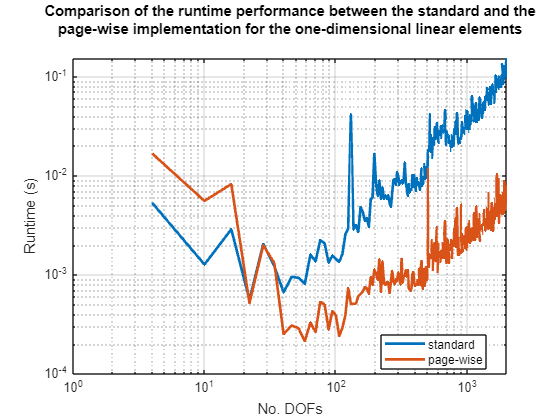

loglog(numDOFsL1, runtimePerformanceL1, LineWidth=2);
legend("standard", "page-wise", Location="best")
grid on;
xlabel("No. DOFs")
ylabel("Runtime (s)")
title(["Comparison of the runtime performance between the standard and the", ...
    "page-wise implementation for the one-dimensional linear elements", ""])

## Runtime performance using sparse matrices and page-wise implementation of the quadratic three-noded finite elements

### Initialize auxiliary variables

numRef = 1000;
stp = 9;
runtimePerformanceL2 = zeros(ceil(numRef/stp), 2);
numDOFsL2 = zeros(ceil(numRef/stp), 1);

### Loop over all the refinement levels

for ii = 1:stp:numRef

#### Generation of the the finite element mesh

    numElL1Ref = ii;
    mshL1Ref = generateLinearMeshOnLine(X0, XL, numElL1Ref);
    numNodesL1Ref = numel(mshL1Ref.nodes);
    mshL2Ref = generateQuadraticMeshOnLine(mshL1Ref);
    numNodesL2Ref = numel(mshL2Ref.nodes);
    numDOFsL2(ceil(ii/stp), 1) = 2*numNodesL2Ref;

#### Definition of the Dirichlet boundary conditions

    freeDOFsL2Ref = 1:2*numNodesL2Ref;
    homDOFsL2Ref = 1:2;
    [~, idxL2Ref] = ismember(homDOFsL2Ref, freeDOFsL2Ref);
    freeDOFsL2Ref(idxL2Ref) = [];

#### Solution of the discrete problem using the page-wise Finite Element implementation with sparse matrices

... starting the timer

    tic;

... computing of the stiffness matrix and consistent nodal force vector for the one-dimensional two-noded linear mesh

    computeStiffMatrixandForceVectorTB = ...
        @computeElementStiffMatrixandForceVectorTimoshenkoBeam;
    computeBasisFunctionsAndDerivs = ...
        @computeQuadraticBasisFunctionsAndFirstDerivatives;
    dummyInp = 'undefined';
    [K, F] = computeMasterStiffMatrixandForceVectorTimoshenkoBeam ...
        (mshL2Ref, computeStiffMatrixandForceVectorTB, computeBasisFunctionsAndDerivs, ...
        dummyInp, propStr);

... solving the discrete linear equation system

    [~] = K(freeDOFsL2Ref, freeDOFsL2Ref)\F(freeDOFsL2Ref);

... stopping the timer

    runtimePerformanceL2((ceil(ii/stp)), 1) = toc;

#### Solution of the discrete problem using the standard Finite Element implementation

... starting the timer

    tic;

... computing of the stiffness matrix and consistent nodal force vector for the one-dimensional two-noded linear mesh

    computeBasisFunctionsAndDerivs = ...
        @computeQuadraticBasisFunctionsAndFirstDerivatives;
    computeStiffMatrixandForceVectorTB = 'undefined';
    dummyInp = 'undefined';
    [K, F] = computeMasterStiffMatrixandForceVectorTimoshenkoBeamPageWise ...
        (mshL2Ref, computeStiffMatrixandForceVectorTB, computeBasisFunctionsAndDerivs, ...
        dummyInp, propStr);

... solving the discrete linear equation system

    [~] = K(freeDOFsL2Ref, freeDOFsL2Ref)\F(freeDOFsL2Ref);

... stopping the timer

    runtimePerformanceL2((ceil(ii/stp)), 2) = toc;

end

### Display of the runtime performance comparison between the standard and the page-wise implementation

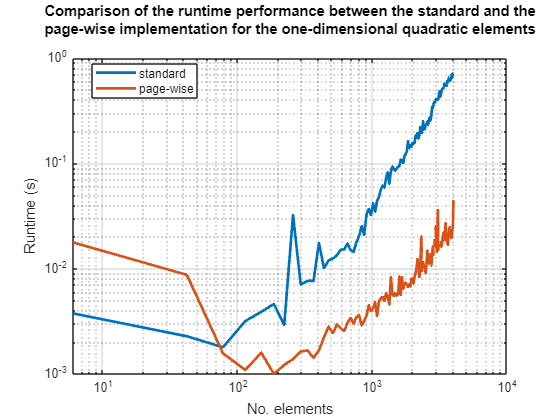

loglog(numDOFsL2, runtimePerformanceL2, LineWidth=2);
legend("standard", "page-wise", Location="best")
grid on;
xlabel("No. elements")
ylabel("Runtime (s)")
title(["Comparison of the runtime performance between the standard and the", ...
    "page-wise implementation for the one-dimensional quadratic elements", ""])

## References

[[1] cane Multiphysics; 2023](https://github.com/andreas-apostolatos/cane)